# **변경사항**

# **Python 설치 및 설정 방법**

**(윈도우 기준)**

- [https://www.python.org/downloads/windows/](https://www.python.org/downloads/windows/) 에서 python 3.7, 3.8, 3.9 버전 중 하나를 windows installer로 다운로드받습니다.

- [https://wikidocs.net/8](https://wikidocs.net/8) 링크의 설명을 따라하여 설치를 완료합니다. Add Python 3.x to PATH 옵션을 꼭 체크합니다.

- windows powershell을 실행합니다. 윈도우 10이면 기본적으로 설치되어 있습니다.

- 입력창에 `python`을 입력하여 python을 실행합니다. python 버전이 설치한 버전과 일치하는지 확인합니다.

- 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

`        import sys`

`        sys.executable`

`pip3 install pandas`

`pip3 install pickle`

## **1.multi-pixel retina data 불러와 channel object 만들기**

**1.1. 파일 전체를 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


tic 

경과 시간은 58.183508초입니다.


%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 소요시간 측정. 적지 않은 시간 소요됨

ans =   PythonEnvironment - 속성 있음:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: Terminated
    ExecutionMode: OutOfProcess


ans =      1     1     0     0
     2     2     0     0
     3     3     0     0
     4     4     0     0
     5     5     0     0
     6     6     0     0
     7     7     0     0
     8     8     0     0
     9     9     0     0
    10    10     0     0


## 2. networkAnalyzer 클래스 인스턴스 생성

**class **`networkAnalyzer`

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9");

Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]


na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]


## 3. 채널 object를 networkAnalyzer에 입력

na.addChannels(reader);

## 4. 채널 위치 입력

%                 channlNum x  y
na.setChannelPosition2d(1 , 0, 0)
na.setChannelPosition2d(2 , 0, 1)
na.setChannelPosition2d(3 , 0, 2)
na.setChannelPosition2d(4 , 0, 3)
na.setChannelPosition2d(5 , 0, 4)
na.setChannelPosition2d(6 , 0, 5)
na.setChannelPosition2d(7 , 0, 6)
na.setChannelPosition2d(8 , 0, 7)
na.setChannelPosition2d(9 , 1, 0)
na.setChannelPosition2d(10, 1, 1)
na.setChannelPosition2d(11, 1, 2)
na.setChannelPosition2d(12, 1, 3)
na.setChannelPosition2d(13, 1, 4)
na.setChannelPosition2d(14, 1, 5)
na.setChannelPosition2d(15, 1, 6)
na.setChannelPosition2d(16, 1, 7)
na.setChannelPosition2d(17, 2, 0)
na.setChannelPosition2d(18, 2, 1)
na.setChannelPosition2d(19, 2, 2)
na.setChannelPosition2d(20, 2, 3)
na.setChannelPosition2d(21, 2, 4)
na.setChannelPosition2d(22, 2, 5)
na.setChannelPosition2d(23, 2, 6)
na.setChannelPosition2d(24, 2, 7)
na.setChannelPosition2d(25, 3, 0)
na.setChannelPosition2d(26, 3, 1)
na.setChannelPosition2d(27, 3, 2)
na.setChannelPosition2d(28, 3, 3)
na.setChannelPosition2d(29, 3, 4)
na.setChannelPosition2d(30, 3, 5)
na.setChannelPosition2d(31, 3, 6)
na.setChannelPosition2d(32, 3, 7)
na.setChannelPosition2d(33, 4, 0)
na.setChannelPosition2d(34, 4, 1)
na.setChannelPosition2d(35, 4, 2)
na.setChannelPosition2d(36, 4, 3)
na.setChannelPosition2d(37, 4, 4)
na.setChannelPosition2d(38, 4, 5)
na.setChannelPosition2d(39, 4, 6)
na.setChannelPosition2d(40, 4, 7)
na.setChannelPosition2d(41, 5, 0)
na.setChannelPosition2d(42, 5, 1)
na.setChannelPosition2d(43, 5, 2)
na.setChannelPosition2d(44, 5, 3)
na.setChannelPosition2d(45, 5, 4)
na.setChannelPosition2d(46, 5, 5)
na.setChannelPosition2d(47, 5, 6)
na.setChannelPosition2d(48, 5, 7)
na.setChannelPosition2d(49, 6, 0)
na.setChannelPosition2d(50, 6, 1)
na.setChannelPosition2d(51, 6, 2)
na.setChannelPosition2d(52, 6, 3)
na.setChannelPosition2d(53, 6, 4)
na.setChannelPosition2d(54, 6, 5)
na.setChannelPosition2d(55, 6, 6)
na.setChannelPosition2d(56, 6, 7)
na.setChannelPosition2d(57, 7, 0)
na.setChannelPosition2d(58, 7, 1)
na.setChannelPosition2d(59, 7, 2)
na.setChannelPosition2d(60, 7, 3)
na.setChannelPosition2d(61, 7, 4)
na.setChannelPosition2d(62, 7, 5)
na.setChannelPosition2d(63, 7, 6)
na.setChannelPosition2d(64, 7, 7)



ans =      1     1     0     0
     2     2     0     1
     3     3     0     2
     4     4     0     3
     5     5     0     4
     6     6     0     5
     7     7     0     6
     8     8     0     7
     9     9     1     0
    10    10     1     1


na.positions

## 4. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

na.bandPass([300,3000])
na.detectSpikes(5,2,2);

number of spikes found : 29
number of spikes found : 66
number of spikes found : 80
number of spikes found : 209
number of spikes found : 220
number of spikes found : 40
number of spikes found : 42
number of spikes found : 120
number of spikes found : 99
number of spikes found : 60
number of spikes found : 9
number of spikes found : 213
number of spikes found : 218
number of spikes found : 218
number of spikes found : 215
number of spikes found : 2
number of spikes found : 100
number of spikes found : 47
number of spikes found : 214
number of spikes found : 215
number of spikes found : 217
number of spikes found : 28
number of spikes found : 40
number of spikes found : 22
number of spikes found : 44
number of spikes found : 49
number of spikes found : 65
number of spikes found : 196
number of spikes found : 206
number of spikes found : 105
number of spikes found : 77
number of spikes found : 2
number of spikes found : 76
number of spikes found : 210
number of spikes found : 204
number 

## 5. 채널의 위치 입력(2d)

na.channels
na.channelList

ans =   Map - 속성 있음:

        Count: 64
      KeyType: double
    ValueType: any


ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10




S = struct(name1, 1, name2, 2)
["a","b"]

figure 3 a, b, c, d, e

아래 사항은 아직 구현하지 않았습니다(reference 12페이지에 있는 내용) 

Since two spike trains with uniformly random activity may exhibit relatively high synchrony merely due to randomness, the SPIKE-distance from recorded data was normalized to random samples generated computationally. That is, for a pair of electrodes with $n_1$ and $n_2$ spikes,

- random spike trains were generated by **sampling $n_1$ and $n_2$ points uniformly at random in a 10-minute timeline.**

- This process was **repeated 1,000 times**, and the **average normalized score** is reported.

filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.pkl"

            0    1    2    3    4    5    6   ...   57   58   59   60   61   62   63
channel0   0.0  1.0  1.0  1.0  1.0  1.0  1.0  ...  1.0  1.0  1.0  1.0  1.0  1.0  1.0
channel1   0.0  0.0  1.0  1.0  1.0  1.0  1.0  ...  1.0  1.0  1.0  1.0  1.0  1.0  1.0
channel2   0.0  0.0  0.0  1.0  1.0  1.0  1.0  ...  1.0  1.0  1.0  1.0  1.0  1.0  1.0
channel3   0.0  0.0  0.0  0.0  1.0  1.0  1.0  ...  1.0  1.0  1.0  1.0  1.0  1.0  1.0
channel4   0.0  0.0  0.0  0.0  0.0  1.0  1.0  ...  1.0  1.0  1.0  1.0  1.0  1.0  1.0
...        ...  ...  ...  ...  ...  ...  ...  ...  ...  ...  ...  ...  ...  ...  ...
channel59  0.0  0.0  0.0  0.0  0.0  0.0  0.0  ...  0.0  0.0  0.0  1.0  1.0  1.0  1.0
channel60  0.0  0.0  0.0  0.0  0.0  0.0  0.0  ...  0.0  0.0  0.0  0.0  1.0  1.0  1.0
channel61  0.0  0.0  0.0  0.0  0.0  0.0  0.0  ...  0.0  0.0  0.0  0.0  0.0  1.0  1.0
channel62  0.0  0.0  0.0  0.0  0.0  0.0  0.0  ...  0.0  0.0  0.0  0.0  0.0  0.0  1.0
channel63  0.0  0.0  0.0  0.0  0.0  0.0  0.0  ...  0.0  0.0  0.0 

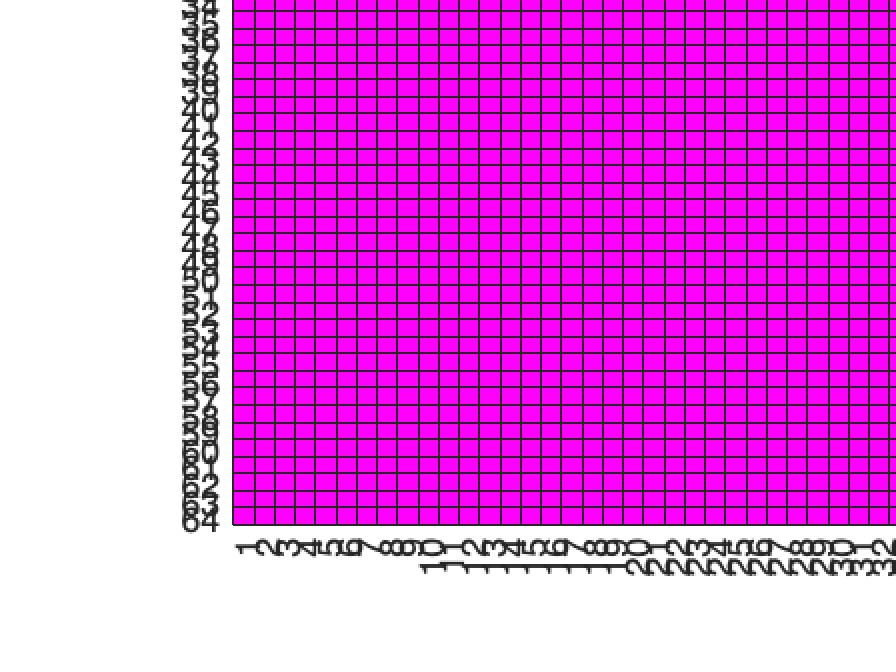

ans =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1 

na.spikeDist()

matlab에서 python을 통해 networkx로 네트워크를 만들고 louvain-python으로 community detection을 하는 것까지는 별 문제가 없으나,

네트워크 모양을 plot으로 그리는 것은 matplotlib 라이브러리를 써야 하는데, 이상하게도 matlab에서 연동이 잘 안됩니다.

차선책으로, score matrix를 파일로 저장한 다음 아예 파이썬 스크립트를 만들고 matlab에서는 해당 파이썬 스크립트를 실행하는 명령만 내리도록 조치하였습니다.

Nodes with the same color (i.e., electrodes) represented the same community network.

The color-mapped synchronization score ranged from 0 (blue) to 1 (red).

In addition, the larger the number of connected electrodes becomes, the larger the size of the node becomes. 

na.louvain()